l = 12 % 单位 cm

l = 12

lambda = 656.3226e-9 

lambda = 6.5632e-07


X = [0.0, 0.8, 1.6, 2.425, 3.285, 4.180]

X =          0    0.8000    1.6000    2.4250    3.2850    4.1800


M = [0 1 2 3 4 5]

M =      0     1     2     3     4     5


Tan = X/l

Tan =          0    0.0667    0.1333    0.2021    0.2737    0.3483


Sin = Tan./sqrt(1 + Tan.^2)

Sin =          0    0.0665    0.1322    0.1981    0.2640    0.3289


d = M*lambda./Sin

d = 1.0e-05 *

       NaN    0.9867    0.9932    0.9940    0.9943    0.9976


N = 1e-3./d

N =        NaN  101.3511  100.6850  100.6006  100.5738  100.2397


clc, clear, close all
data_LED = readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\10-傅里叶光学\data\光谱仪数据 (2024-11-05 傅里叶光学)\白光 LED.txt")
data_Laser = readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\10-傅里叶光学\data\光谱仪数据 (2024-11-05 傅里叶光学)\红光激光.txt")
data_light = readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\10-傅里叶光学\data\光谱仪数据 (2024-11-05 傅里叶光学)\手机手电筒.txt")

stc = MyPlot([data_LED(:, 1), data_Laser(:, 1), data_light(:, 1)]', [data_LED(:, 2), data_Laser(:, 2), data_light(:, 2)]');
c = GetMyColors;
stc.plot.plot_2.Color = c{10};
stc.plot.plot_2.LineStyle = '-';
stc.plot.plot_3.LineStyle = '-';
y = ylim
stc.axes.YLim = [y(1, 1), 5e4];
stc.label.x.String = '$\lambda$ (nm)';
stc.label.y.String = 'Indensity';
stc.leg.String = ["White LED"; "Red Laser"; "Phone Flashlight"];

%MyExport_pdf_docked

x = data_Laser(:, 1)
y = data_Laser(:, 2)

lam = linspace(500, 800, 100000);
lam(2) - lam(1)

[M, I] = max(RadLaser_fit(lam))
lam(I)

fplot(@(x) RadLaser_fit(x), [650, 665])
vpa(goodness.rsquare)
vpa(goodness.adjrsquare)

sca = MyScatter(x', y');
x_array = [linspace(600, 650, 300), linspace(650, 665, 400), linspace(665, 710, 400)]

x_array =   600.0000  600.1672  600.3344  600.5017  600.6689  600.8361  601.0033  601.1706  601.3378  601.5050  601.6722  601.8395  602.0067  602.1739  602.3411  602.5084  602.6756  602.8428  603.0100  603.1773  603.3445  603.5117  603.6789  603.8462  604.0134  604.1806  604.3478  604.5151  604.6823  604.8495  605.0167  605.1839  605.3512  605.5184  605.6856  605.8528  606.0201  606.1873  606.3545  606.5217  606.6890  606.8562  607.0234  607.1906  607.3579  607.5251  607.6923  607.8595  608.0268  608.1940


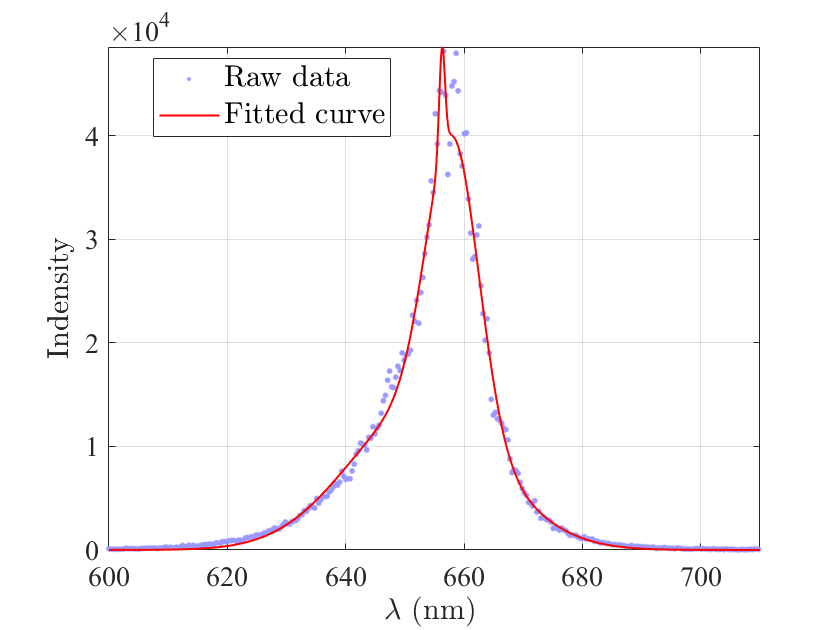

x_array = 1.0e+03 *

    0.3500    0.3510    0.3520    0.3530    0.3540    0.3550    0.3560    0.3570    0.3580    0.3590    0.3600    0.3610    0.3620    0.3630    0.3640    0.3651    0.3661    0.3671    0.3681    0.3691    0.3701    0.3711    0.3721    0.3731    0.3741    0.3751    0.3761    0.3771    0.3781    0.3791    0.3801    0.3811    0.3821    0.3831    0.3841    0.3851    0.3861    0.3871    0.3881    0.3891    0.3901    0.3911    0.3921    0.3931    0.3941    0.3952    0.3962    0.3972    0.3982    0.3992


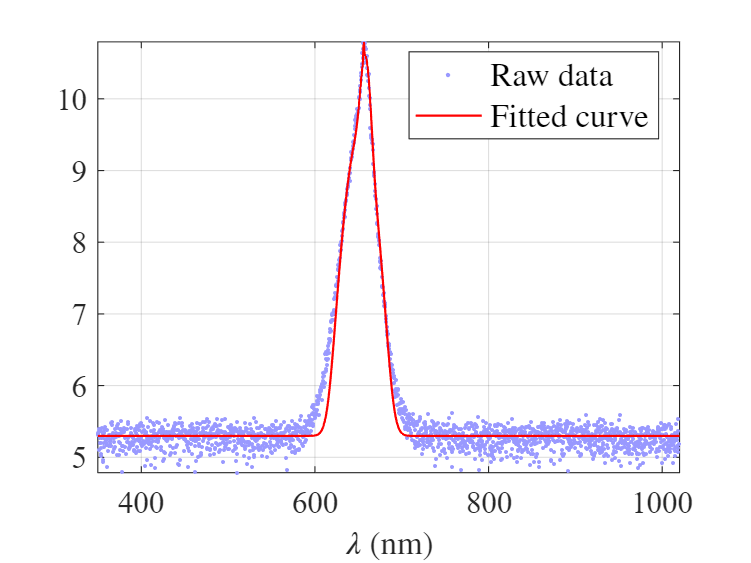

x_array = 1.0e+03 *

    0.3500    0.3510    0.3520    0.3530    0.3540    0.3550    0.3560    0.3570    0.3580    0.3590    0.3600    0.3610    0.3620    0.3630    0.3640    0.3651    0.3661    0.3671    0.3681    0.3691    0.3701    0.3711    0.3721    0.3731    0.3741    0.3751    0.3761    0.3771    0.3781    0.3791    0.3801    0.3811    0.3821    0.3831    0.3841    0.3851    0.3861    0.3871    0.3881    0.3891    0.3901    0.3911    0.3921    0.3931    0.3941    0.3952    0.3962    0.3972    0.3982    0.3992


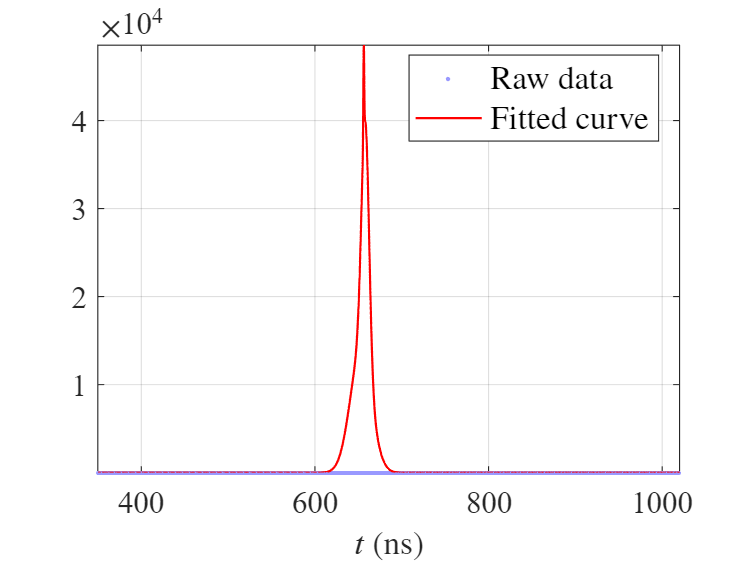

p1 = MyPlot_ax(sca.axes, x_array, RadLaser_fit(x_array)');
MyColors = GetMyColors;
sca.scatter.scatter_1.SizeData = 80;
sca.scatter.scatter_1.MarkerEdgeColor = MyColors{1};

%xline(0, 'Color', [0.5, 0.5, 0.5])
%yline(0, 'Color', [0.5, 0.5, 0.5])

p1.plot.plot_1.LineWidth = 1;
p1.plot.plot_1.Color = 'r';
p1.label.x.String = '$\lambda$ (nm) ';
p1.label.y.String = 'Indensity';
p1.leg.String = ["Raw data"; "Fitted curve"];
xlim([x_array(1), x_array(end)])
MyExport_pdf_docked

%dfit = diff(@(x) RadLaser_fit(x))
[d1, d2] = differentiate(RadLaser_fit, x)

d1 = 1.0e+04 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


d2 = 1.0e+04 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


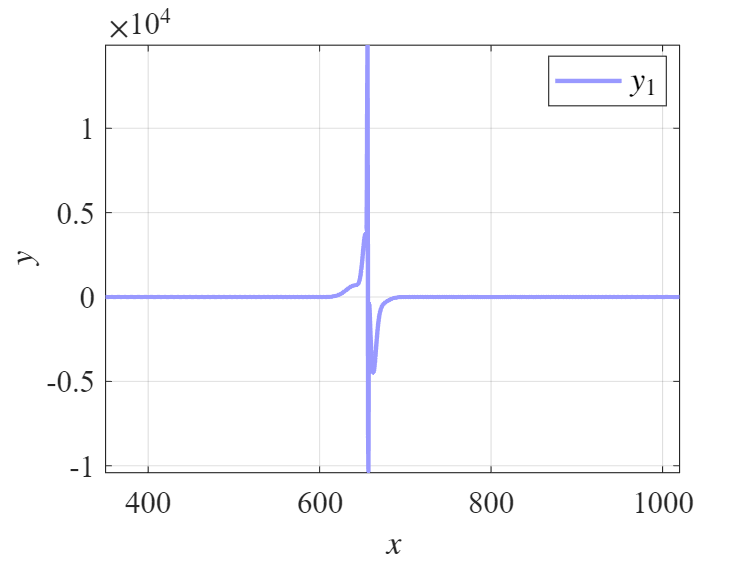

ans = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]



MyPlot(x', d1')